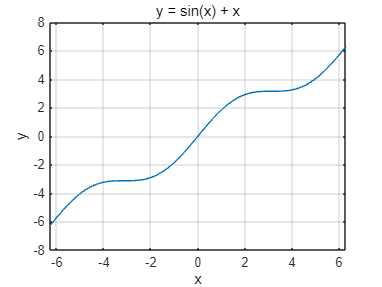

% x 값의 범위 설정
x = -2*pi:0.01:2*pi;

% y = sin(x) + x 함수 정의
y = sin(x) + x;

% 그래프 그리기
plot(x, y);
xlabel('x');
ylabel('y');
title('y = sin(x) + x');
grid on;

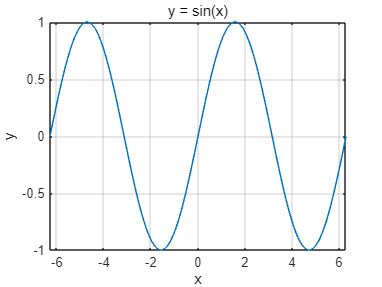

% x 값의 범위 설정
x = -2*pi:0.01:2*pi;

% y = sin(x) 함수 정의
y = sin(x);

% 그래프 그리기
plot(x, y);
xlabel('x');
ylabel('y');
title('y = sin(x)');
grid on;

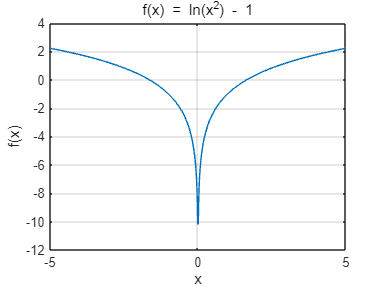

% x 값의 범위 설정
x = -5:0.01:5;

% 첫 번째 함수: f(x) = ln(x^2) - 1
y1 = log(x.^2) - 1;

% 두 번째 함수: f(x) = e^(-0.2x) * sin(3x - 0.5)
y2 = exp(-0.2 * x) .* sin(3 * x - 0.5);

% 첫 번째 함수 그래프 그리기
figure;
plot(x, y1);
xlabel('x');
ylabel('f(x)');
title('f(x) = ln(x^2) - 1');
grid on;

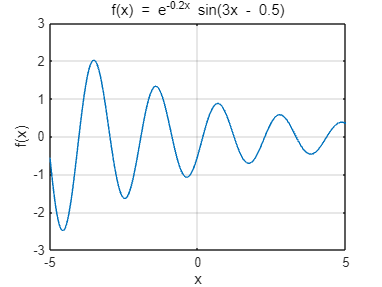


% 두 번째 함수 그래프 그리기
figure;
plot(x, y2);
xlabel('x');
ylabel('f(x)');
title('f(x) = e^{-0.2x} sin(3x - 0.5)');
grid on;

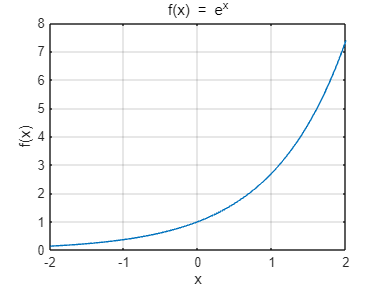

% x 값의 범위 설정
x1 = -2:0.01:2; % e^x를 위한 범위
x2 = 0.01:0.01:5; % ln(x)를 위한 범위 (x > 0)

% 첫 번째 함수: f(x) = e^x
y1 = exp(x1);

% 두 번째 함수: f(x) = ln(x)
y2 = log(x2);

% 첫 번째 함수 그래프 그리기
figure;
plot(x1, y1);
xlabel('x');
ylabel('f(x)');
title('f(x) = e^x');
grid on;

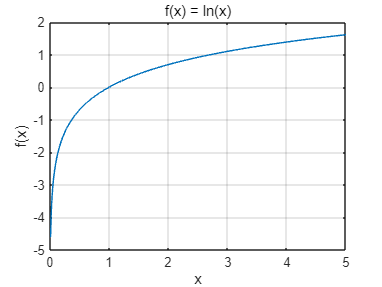


% 두 번째 함수 그래프 그리기
figure;
plot(x2, y2);
xlabel('x');
ylabel('f(x)');
title('f(x) = ln(x)');
grid on;

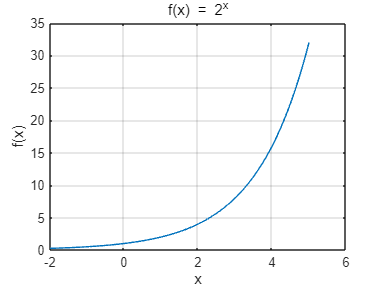

% x 값의 범위 설정
x1 = -2:0.01:5; % 2^x를 위한 범위
x2 = 0.01:0.01:5; % log(x)를 위한 범위 (x > 0)

% 첫 번째 함수: f(x) = 2^x
y1 = 2.^x1;

% 두 번째 함수: f(x) = log(x)
y2 = log10(x2); % MATLAB에서는 log10 함수가 일반 로그를 나타냄

% 첫 번째 함수 그래프 그리기
figure;
plot(x1, y1);
xlabel('x');
ylabel('f(x)');
title('f(x) = 2^x');
grid on;

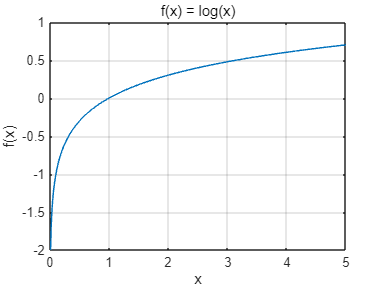


% 두 번째 함수 그래프 그리기
figure;
plot(x2, y2);
xlabel('x');
ylabel('f(x)');
title('f(x) = log(x)');
grid on;

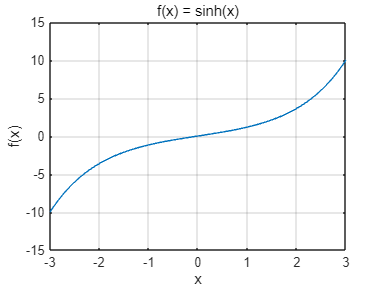

% x 값의 범위 설정
x = -3:0.01:3;
x_pos = 0:0.01:3; % 역쌍곡코사인과 역쌍곡탄젠트의 정의역에 맞게 양수 범위 설정
x_artanh = -0.99:0.01:0.99; % 역쌍곡탄젠트 정의역 (-1, 1)

% 쌍곡사인 함수: sinh(x)
y_sinh = sinh(x);

% 쌍곡코사인 함수: cosh(x)
y_cosh = cosh(x);

% 쌍곡탄젠트 함수: tanh(x)
y_tanh = tanh(x);

% 역쌍곡사인 함수: arsinh(x)
y_arsinh = asinh(x);

% 역쌍곡코사인 함수: arcosh(x)
y_arcosh = acosh(x_pos); % x >= 1

% 역쌍곡탄젠트 함수: artanh(x)
y_artanh = atanh(x_artanh); % |x| < 1

% 쌍곡사인 그래프 그리기
figure;
plot(x, y_sinh);
xlabel('x');
ylabel('f(x)');
title('f(x) = sinh(x)');
grid on;

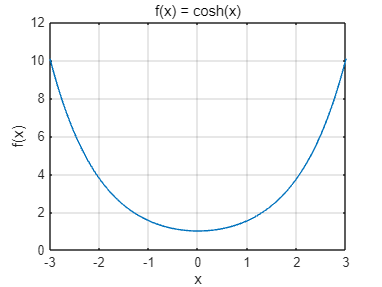


% 쌍곡코사인 그래프 그리기
figure;
plot(x, y_cosh);
xlabel('x');
ylabel('f(x)');
title('f(x) = cosh(x)');
grid on;

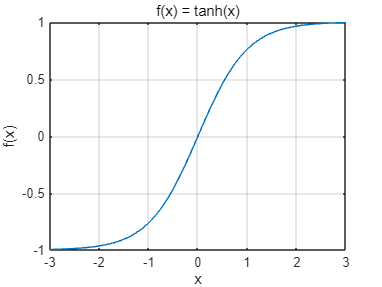


% 쌍곡탄젠트 그래프 그리기
figure;
plot(x, y_tanh);
xlabel('x');
ylabel('f(x)');
title('f(x) = tanh(x)');
grid on;

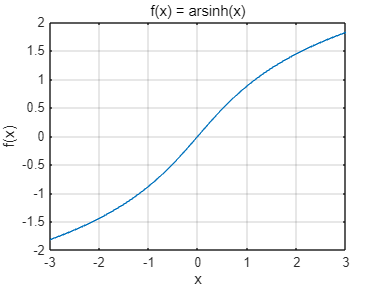


% 역쌍곡사인 그래프 그리기
figure;
plot(x, y_arsinh);
xlabel('x');
ylabel('f(x)');
title('f(x) = arsinh(x)');
grid on;


% 역쌍곡코사인 그래프 그리기
figure;
plot(x_pos, y_arcosh);

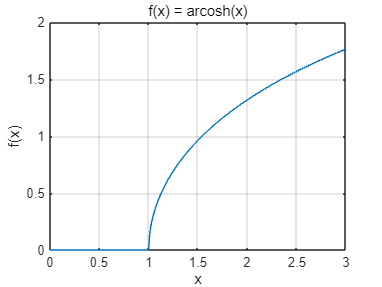

xlabel('x');
ylabel('f(x)');
title('f(x) = arcosh(x)');
grid on;

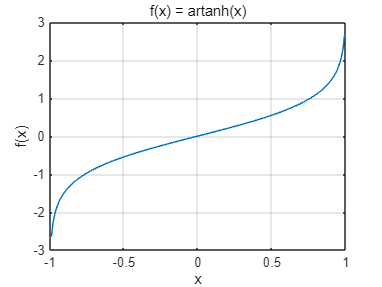


% 역쌍곡탄젠트 그래프 그리기
figure;
plot(x_artanh, y_artanh);
xlabel('x');
ylabel('f(x)');
title('f(x) = artanh(x)');
grid on;

**이분법 알고리즘 개요**

- **근 찾는 수치 기법**은 근의 근사 위치를 미리 알고 있어야 하며, 시작을 위해 초기 실근값이 필요함.

- **중간값 정리**를 기반으로, 함수가 근의 근처에서 부호가 변한다는 사실을 이용.

- 두 개의 초기 가정값이 필요하며, 이 때문에 **구간법**으로 분류됨.

**이분법 알고리즘 과정 (Pseudocode)**

- **초기 구간 선택:**

- $f(x_l)f(x_u) < 0$이 되도록 $x_l$과 $x_u$�를 선택.

- **중간점 계산:**

- $x_r$ 결정:$x_l$과 $x_u$의 평균.

$x_r = \frac{x_l + x_u}{2}$��

- **구간 변경:**

- $f(x_l)f(x_r) < 0$이면 $x_u = x_r$�.

- $f(x_l)f(x_r) > 0$이면 $x_l = x_r$.

- $f(x_l)f(x_r) = 0$이면 $x_r$�이 근이므로 종료.

- **종료 조건 확인:**

- $\epsilon_a \leq \epsilon_s$�이면 종료.

- $\epsilon_a > \epsilon_s$�이면 Step 2로 이동.

**종료 판정 기준**

- **오차**가 미리 정한 정밀도 이하로 떨어지면 반복을 종료.

- **상대 오차 ($\epsilon_a$�)**의 공식: $\epsilon_a = \left| \frac{x_{\text{new}} - x_{\text{old}}}{x_{\text{new}}} \right| \times 100 \leq \epsilon_s$�

- $x_{\text{new}}$�: 새로운 중간값

- $x_{\text{old}}$�: 이전 중간값

- $\epsilon_s$�: 허용 오차

**이분법 알고리즘 과정 (Pseudocode)**

- **초기 구간 선택:**

- $f(x_l)f(x_u) < 0$이 되도록 $x_l$과 $x_u$를 선택.

- **중간점 계산:**

- $x_r$ 결정: $x_l$과 $x_u$�의 평균.

$2x_r = \frac{x_l + x_u}{2}$��

- **구간 변경:**

- $f(x_l)f(x_r) < 0$이면 $x_u = x_r$.

- $f(x_l)f(x_r) > 0$이면 $x_l = x_r$�.

- $f(x_l)f(x_r) = 0$이면 $x_r$�이 근이므로 종료.

- **종료 조건 확인:**

- $\epsilon_a \leq \epsilon_s$�이면 종료.

- $\epsilon_a > \epsilon_s$�이면 Step 2로 이동.

**설명**

- **이분법**은 근이 존재하는 범위를 반복적으로 반으로 나누어 근을 찾는 방법입니다.

- **중간값 정리**를 이용하여 함수가 연속이고 구간의 양 끝점에서 함수값의 곱이 음수인 경우, 그 구간에 근이 존재함을 보장합니다.

- **장점**: 간단하고 안정적이지만, 근을 찾는 속도가 느릴 수 있습니다.

- **단점**: 초기 구간을 잘 선택해야 하며, 근이 한 개만 있는 경우에만 사용이 효과적입니다.

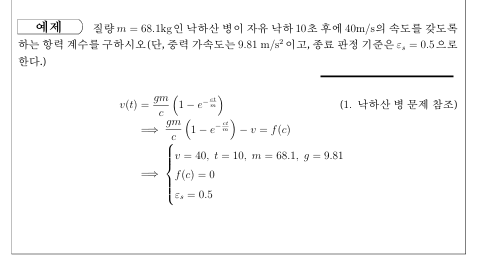

% 초기 변수 설정
m = 68.1;  % 질량 (kg)
g = 9.81;  % 중력 가속도 (m/s^2)
v = 40;    % 속도 (m/s)
t = 10;    % 시간 (s)
es = 0.5e-5;  % 허용 오차 (%)

% 속도 함수 정의
v_func = @(c) (g * m / c) * (1 - exp(-c * t / m)) - v;

% 이분법을 위한 초기 구간 설정
xl = 12;
xu = 16;
ea = 100;  % 초기 오차
x_new = (xl + xu) / 2; % x_new 초기화
xr_old = x_new; % x_new 값을 xr_old에 할당

% 이분법 알고리즘 수행
while ea > es
    xr = (xl + xu) / 2;  % 중간값 계산
    if v_func(xl) * v_func(xr) < 0
        xu = xr;
    elseif v_func(xl) * v_func(xr) > 0
        xl = xr;
    else
        break; % 정확한 근을 찾은 경우
    end
    
    % 상대 오차 계산
    if xr ~= 0
        ea = abs((xr - xr_old) / xr) * 100;
    end
    xr_old = xr;
end

% 결과 출력
fprintf('항력 계수 c = %.4f\n', xr);

항력 계수 c = 14.0000


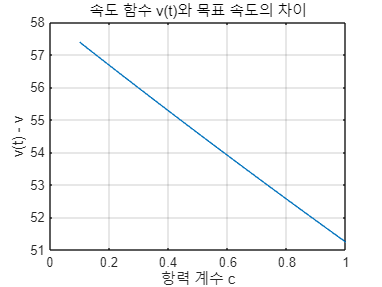


% 속도 함수의 시각화
c_values = linspace(0.1, 1, 100); % c의 범위 설정
v_values = arrayfun(v_func, c_values);

figure;
plot(c_values, v_values);
xlabel('항력 계수 c');
ylabel('v(t) - v');
title('속도 함수 v(t)와 목표 속도의 차이');
grid on;

% 초기 변수 설정
m = 68.1;  % 질량 (kg)
g = 9.81;  % 중력 가속도 (m/s^2)
v = 40;    % 속도 (m/s)
t = 10;    % 시간 (s)
err_s = 0.5e-2; % 허용 오차

% 속도 함수 정의
func = @(c) g.*m./c .* (1 - exp(-c.*t./m)) - v;

x = [12, 16]; % 초기 구간
x_new = 12;
x_old = 16;

iter = 0; % 반복 횟수
% 이분법 실행
while true
    iter = iter + 1;
    f = func(x); % 현재 구간에서 함수 값 계산
    
    % 근 교체
    x_old = x_new;
    x_new = mean(x);
    
    err_a = abs((x_new - x_old) / (x_new)); % 상대 오차 계산

    fprintf("iter : %2d, root : %6.4f, err : %8.6f\n", iter, x_new, err_a);

    f_r = func(x_new);
    if (err_a <= err_s) || (f_r == 0), break; end % 허용 오차 확인

    % 구간 변경
    f = f(1) * f_r;
    if f < 0, x(2) = x_new;
    else, x(1) = x_new; end
end

iter :  1, root : 14.0000, err : 0.142857
iter :  2, root : 15.0000, err : 0.066667
iter :  3, root : 14.5000, err : 0.034483
iter :  4, root : 14.7500, err : 0.016949
iter :  5, root : 14.8750, err : 0.008403
iter :  6, root : 14.8125, err : 0.004219
